**The following are symbols in use**

s=tf('s');

**The following are the constant varible which will be taken in use**

K = 0.530516; % Motorconstant
La = 3.3475; % Inductance in mH
Ra = 6.8144; % Resistance in ohm
B = 0.000931; % Motror frictions koefficient
J =0.0019; % Motor intertimoment kg*m^2

J_bcs= 0.0889; % Intertimoment for pan/tilt i best kg*m^2
J_wcs= 0.0946; % Intertimoment for pan/tilt i worst kg*m^2

**The following are the performance specifications**

tr = 1;  % Rise time
Mp = 0.1;   % Overshoot
ts = 3;   % Settling time

% Below is in freqency domain

wn = 1.8/tr;
zeta = sqrt(((log(Mp)/-pi)^2)/(1+(log(Mp)/-pi)^2));
sigma = 4.6/ts;

**The following is the three transfer functions**

TF_p =K/(s*((Ra + La)*(J*s + B) + K)); %Position
TF_v =K/((Ra + La)*(J*s+B)+K); %Velocity
TF_c =1/(Ra + La*s + ((K*s)/(J*s^2+B*s))); %Current

**The following is the begining of finding a suitable controller for the system**

Encoder =200 khz

ADC_current = 1 mhz

ca 5 gange hurtigere

**The following is a straight forward controller with no cascade**

The idea is to compare it with a cascade controller, in order to beable to prove that it should be better than a straigt forward

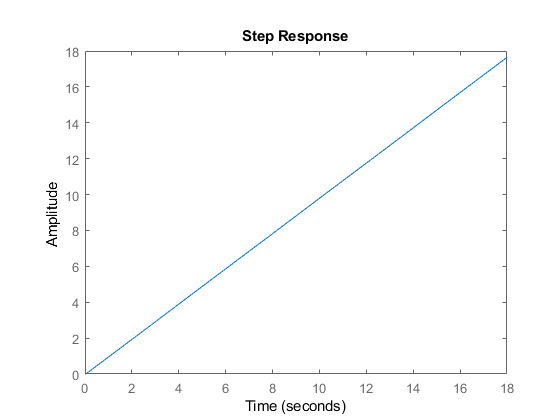

step(TF_p); % The motors behavier 

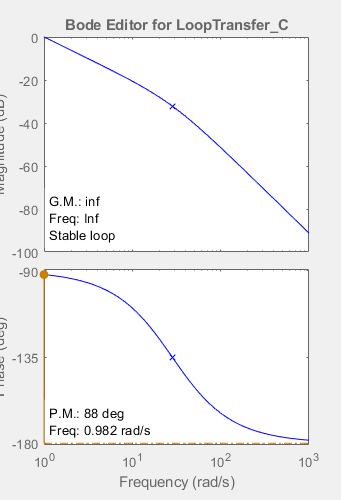

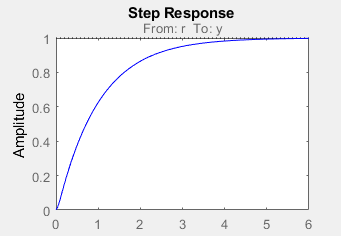

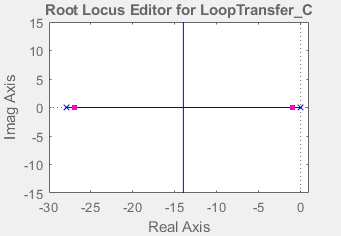

controlSystemDesigner(TF_p) % Designing a regulator


% Indre = strøm, Næste = hastighed, yderste = positionen

% Ligge den indresløjfe i FPGA? Da den skal køre med ret høj frekvens = høj
% samplingfrekvens. 50 khtz på den indre.

% Implementering af tidskonstanter (Den indre regulator skal bare være hurtige som regulator end den næste)
% Performance specifikationer skal vi have forskellige?